Author: Dylan Lozon

Class: ECE 101

Assignment: Exercise 3

Date: Apr 18 2023 

## Create array of 0's

map = zeros(20,20); % Size 10x10

## Create a flat area up high 

% Place the flat area along the right edge of the map at height 8
map(:, 16:20) = ones(20,5) * 8;

## Create the ramp structure

% Define a slope that comes down to the left
slopeDown = linspace(-2,8,10);
% Define a gentler slope that goes up to the left
slopeUp = linspace(0,-2,3);

% Apply the ramp slope to each row on the map
for i = 1:20
    map(i,7:16) = slopeDown; % Go down
    map(i,6) = -2; % Breifly flatten out for a curve
    map(i,4:6) = slopeUp; % Go up
end

## Display the completed structure

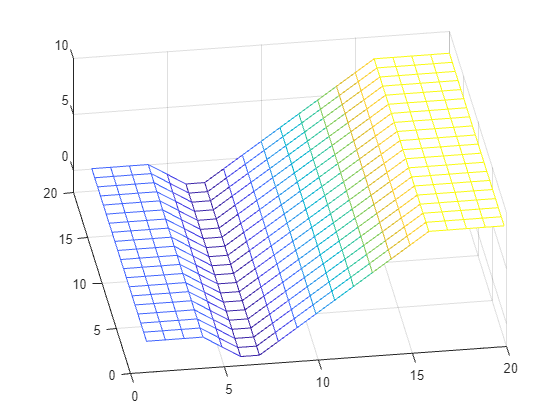

mesh(map); % Display the mesh
view([-8.70 54.00]); % View from a good angle